# Monte Carlo Method - Approximation of Pi

The Monte Carlo method is a method to understand problems based on probability. At their most basic, a model is run many times using randomly generated input values pulled from a reasonable range for those inputs. While any one run doesn't provide much information, looking at the aggregate results of many runs shows how uncertainty from individual inputs interact and provides an approximate solution or distribution for the model.

There are many creative ways to approximate the numeric value of pi, such as Buffon's needle problem, that utilize the Monte Carlo method. However, we are going to use a simpler method. Imagine that you have square and inscribe a quadrant (quarter circle) inside - see figure below. If you uniformly scattered a given number of points over the square, the ratio of the number of points that fall inside the quandrant to the total number of points will approximate $\frac{\pi}{4}$.

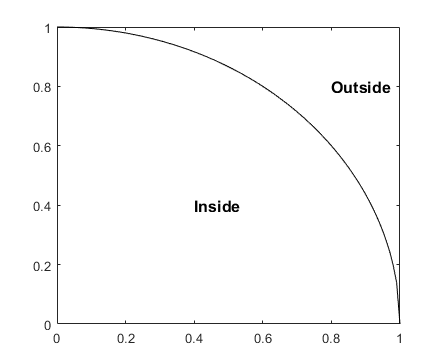

We can model this in MATLAB  using the `rand` function to generate an x and y location for a point, counting if that point falls inside the circle, and repeating that process for a set number of points. 

#### Part a)

Write a program, where the user will set the number of points to model in a variable named `n. T`hen, using a for loop, generate those points one at a time and count how many fall inside the circle (i.e., how many of a distance from the origin of less than or equal to one). Calculate the approximate value of pi by multiplying four times the ratio of points that fall inside the circle to the total number of points.


$$\pi\approx4\left(\frac{Points_{inside}}{Points_{Total}}\right)$$


#### Part b)

Because you want to see how the number of points used affects the approximation of pi, you want to run the program written in Part a for `n-`values ranging from 10 to 15000, in increments of 10 (i.e., 10, 20, 30, ... 14990, 15000). Modify your Part a program to be run once for each of these `n`-values and create a matrix `Results` where the first column contains the `n`-value for each of the runs and the second column contains the approximation of pi for that `n`-value.

Assuming the `Results` matrix is properly created, running the following line in the command window should generate a plot showing how the value of pi converges as the number of points is increased.

`plot(Results(:,1),Results(:,2),'xk')`

clc;clear;

## Program


x=rand;
y=rand;

square=0;
C=0

C = 0

inc=0
Results=[]


Results =

     []



Results1=0

Results1 = 0

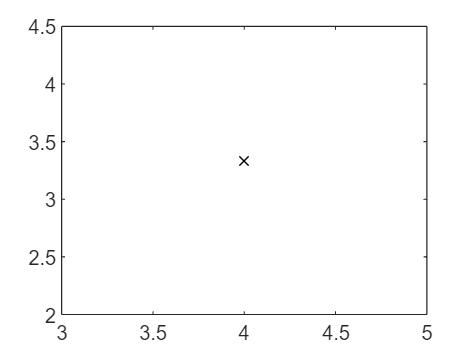

for n=10:10:15000
    CirVal=0;
    inc=inc+1
    for M=1:n
        
        x=rand;
        y=rand;
        if (x^2+y^2)<1
            CirVal=CirVal+1;
        else
            square=square+1;
        end
       
    end
       Results1=4*(CirVal/(square+CirVal));
       Results=[Results,Results1];
      
end
 plot(Results(:,1),Results(:,2),'xk')